clearvars; close all; clc;

# Bandpass 4th order

disp(string(datetime("today")))

11-Feb-2026


JVsound, J.G. Vermond

## Summary

A bandpass enclosure, 4th order, with a B&C speaker. We compare Hornresp results with our own audio toolbox results. A finite element model is made for a custom 21" bandpass cabinet.

## Import Hornresp results

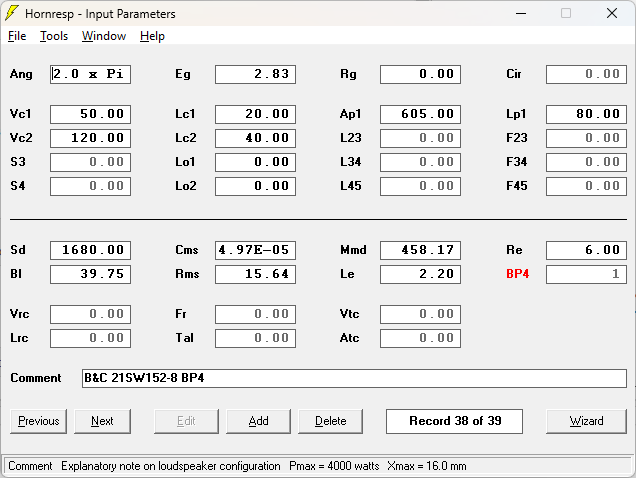

% Acoustic power
bp4hrpow	= load("bp4hrpow.mat").bp4hrpow;
% Electric impedance
bp4hrimp	= load("bp4hrimp.mat").bp4hrimp;
% Displacement
bp4hrdispl	= load("bp4hrdispl.mat").bp4hrdispl;

### Acoustic power

Acoustic power, or sound power is neither room-dependent nor distance-dependent. Sound power is a property of a sound source, equal to the total power emitted by that source in all directions. Sound power level is a logarithmic measure of the power of a sound relative to a reference value:


$$L_W = 10\log_{10}\left(\frac{P}{P_{ref}} \right)dB$$


where

- $P$ is the sound power,

- $P_{ref}$ is the reference sound power: 1e-12W.

Hornresp's acoustic power window is a bit misleading and is actually the pressure at a spherical $Q=1$, half spherical $Q=2$, or quarter spherical $Q=4$ surface, as a result of a acoustic power source.


$$p_{ref} = \sqrt{\frac{Q\rho_0cP_{ref}}{4\pi r^2}} \rightarrow P_{ref} = \frac{p_{ref}^2 4\pi r^2}{Q\rho_0c}$$


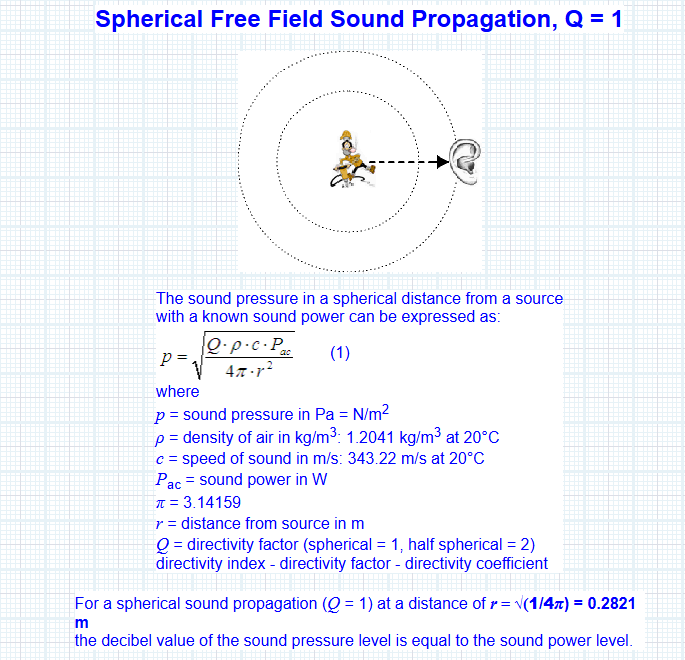

## Speaker

We load the B&C 21SW152-8 speaker file:

bc		= load("bc21sw152_8.mat").bc21sw152_8;

## Finite element analysis

A quarter symmetry model is made in ANSYS.

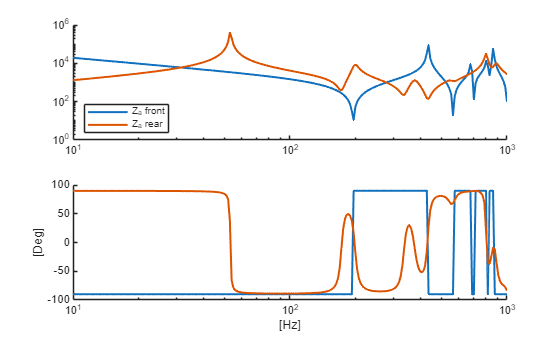

feai					= fea.feaimport;
feai.xdot				= 1e-3;
feai.sd					= bc.sd;
feai.fnamediaphragmf	= "bp4f.txt";
feai.fnamediaphragmr	= "bp4r.txt";
feai.fnamexdottopres	= "bp4p0.txt";

zafront = feai.zafront;
zarear = feai.zarear;
zaf		= feai.fans;

save bp4refza zarear zafront zaf

fig1					= figure;
ax11					= subplot(2,1,1,parent=fig1); hold on;
ax12					= subplot(2,1,2,parent=fig1); hold on; 
ax11.XScale				= "log";
ax11.YScale				= "log";
ax12.XScale				= "log";
ax12.XLabel.String		= "[Hz]";
ax12.YLabel.String		= "[Deg]";

plot(ax11,feai.fans,abs(feai.zafront),LineWidth=1.5)
plot(ax12,feai.fans,angle(feai.zafront)*180/pi,LineWidth=1.5)

plot(ax11,feai.fans,abs(feai.zarear),LineWidth=1.5)
plot(ax12,feai.fans,angle(feai.zarear)*180/pi,LineWidth=1.5)

leg11 = legend(ax11,"Z_a front","Z_a rear",Location="southwest");

## Simulation object

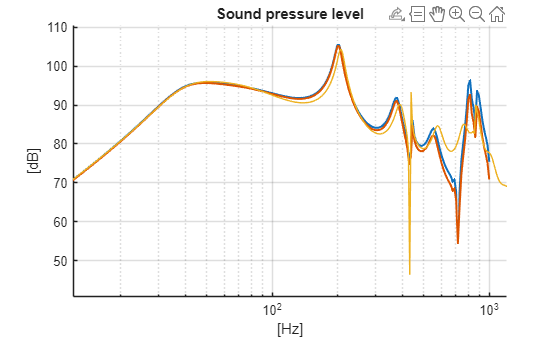

s			= acoustics.simulation(feai.fans);
s.feai		= feai;
s.sp		= bc;

spl			= s.spl;
swl			= s.swl;

fig2				= figure;
ax2					= axes(fig2); hold on; grid on;
ax2.XScale			= "log";
ax2.XLim			= [s.f(1) s.f(end)];
ax2.XLabel.String	= "[Hz]";
ax2.YLabel.String	= "[dB]";
ax2.Title.String	= "Sound pressure level";

plot(ax2,s.f,spl,LineWidth=1.5)
plot(ax2,s.f,swl,LineWidth=1.5);

plot(ax2,bp4hrpow.Freqhertz,bp4hrpow.SPLdB)

## Appendix A: acoustic impedance

Acoustic impedance for a specific frequency.

% Frequency:
f			= 52.831;

% Find index in array:
[~,idx]		= min(abs(s.f-f));

% Load radiation impedance from ANSYS
bp4radimp		= load("bp4radimp.mat").bp4radimp;
zarad			= (bp4radimp.RealMPa' + 1i*bp4radimp.ImaginaryMPa') * 1e6;
zacp			= feai.zarear - zarad;

Rar				= real(zarad(idx))

Rar = 0.0038

Xar				= imag(zarad(idx))

Xar = 0.0456


Racp			= real(zacp(idx))

Racp = 3.1886e+05

Xacp			= imag(zacp(idx))

Xacp = 2.5287e+05

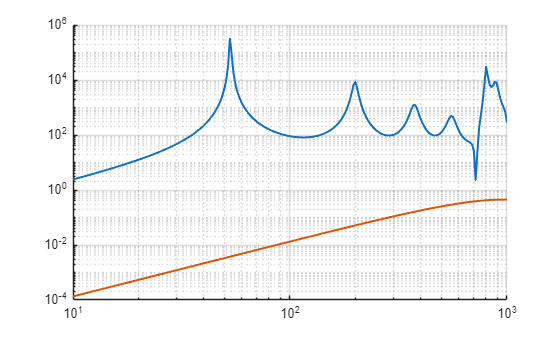

% % Load radiation impedance from ANSYS:
% bp4radimp		= load("bp4radimp.mat").bp4radimp;
% zarad			= (bp4radimp.RealMPa + 1i*bp4radimp.ImaginaryMPa) * 1e6;
% zar				= feai.zarear - zarad';

figa		= figure;
axa			= axes(figa); hold on; grid on;
axa.XScale	= "log";
axa.YScale	= "log";

plot(axa,s.f,real(feai.zarear),LineWidth=1.5)
plot(axa,s.f,real(zarad),LineWidth=1.5)

% plot(axa,s.f,real(zar),LineWidth=1.5,LineStyle="--")